# 3次元点群の形式の1つであるe57ファイルについて

## はじめに

この記事はMATLAB/Simulink Advent Calendar 2023の9日目の記事として書かれています。

LiDARなどにより取得される点群ファイルの有名なフォーマットにe57があります。

e57は、XML データ形式に基づいて点群や各種データを階層ツリー構造で格納します。米国試験材料協会 (ASTM) によって定められています。

例えば、Leica社のCycloneで点群をエキスポートするときや、iPhone LiDARのアプリである、Dot3Dで点群をエキスポートするときにE57形式を選択することができます。

以下の図は、Dot3Dで点群をエキスポートするときの様子です。一番下にE57があることがわかります。

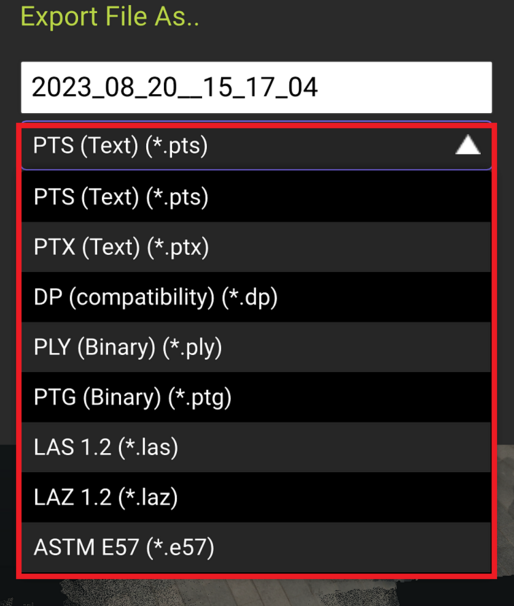

## E57形式について

E57は、ヘッダー、バイナリーセクション、XMLセクションに分かれています。

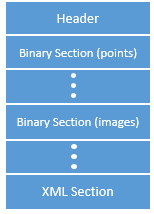

また、データ構造は以下のようになっています。Dota3Dという3次元的なデータと、Images2Dとあるような２次元的なデータに分かれています。高密度点群の標準的なフォーマットであるLAS形式の違いとして、スキャンごとの点群やその点群を取得した時の位置や姿勢、また、画像に関する情報が分かれていることが挙げられます。

LAS形式では、スキャンごとの点群は合成され、また、各点にRGBの色情報が投影された状態で保存されます。

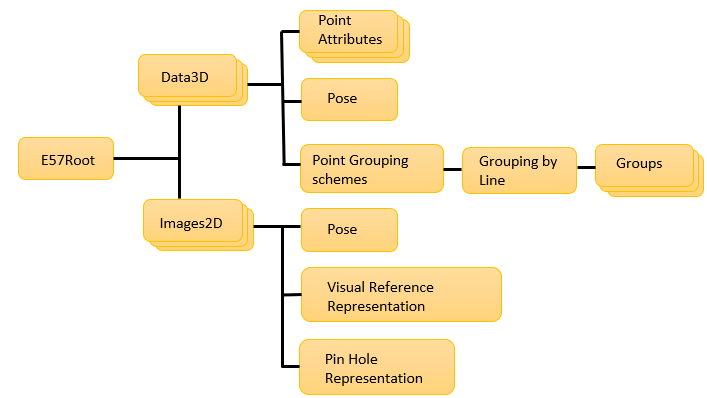

[https://jp.mathworks.com/help/lidar/ref/e57filereader.html#mw_4c374fdf-2a4b-4a56-a517-e6aa3656d173](https://jp.mathworks.com/help/lidar/ref/e57filereader.html#mw_4c374fdf-2a4b-4a56-a517-e6aa3656d173)

## 姿勢情報について

E57形式ではスキャンが行われた時の位置や向きが格納されています。そのため、E57形式を開けば、各スキャンでの点群が取得でき、さらにその姿勢情報を利用して点群を変換することで、それぞれのスキャンを合成できると考えられます。

## MATLABコード

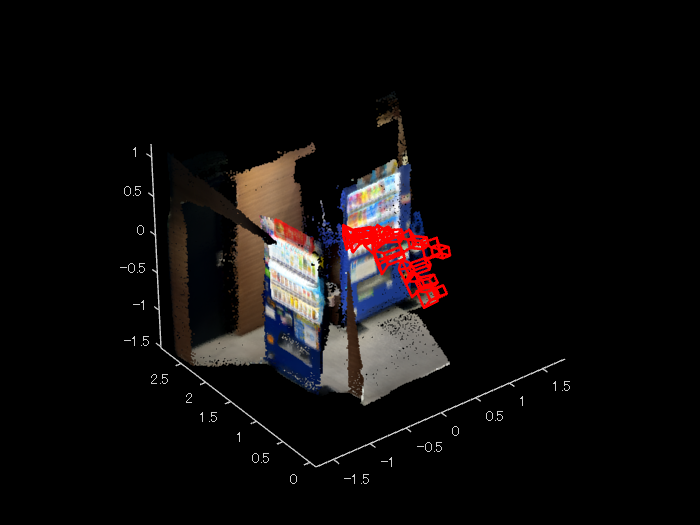

clear;clc;close all

e57Reader = e57FileReader("lobby.e57");
% 点群 ptCloudArr および対応する姿勢 tformArr を格納するための変数を定義します。
ptCloudArr = [];
tformArr = []; 
absTform   = rigidtform3d; 
% 点群データを読み取ります。

% for i = 1:e57Reader.NumPointClouds
for i = 1:10
   [ptCloud,pcMetadata] = readPointCloud(e57Reader,i);
    for j = 1:numel(ptCloud)
        ptCloudArr = [ptCloudArr ptCloud(j)];
        tformArr = [tformArr pcMetadata.RelativePose];
        % absTform = rigidtform3d(absTform.A * pcMetadata.RelativePose.A );
        cam = plotCamera(AbsolutePose=pcMetadata.RelativePose,Opacity=0,Size=0.1);hold on        
    end
end
pcMap = pcalign(ptCloudArr,tformArr); 
pcMapDown = pcdownsample(pcMap,"random",0.1);

pcshow(pcMapDown);hold on;

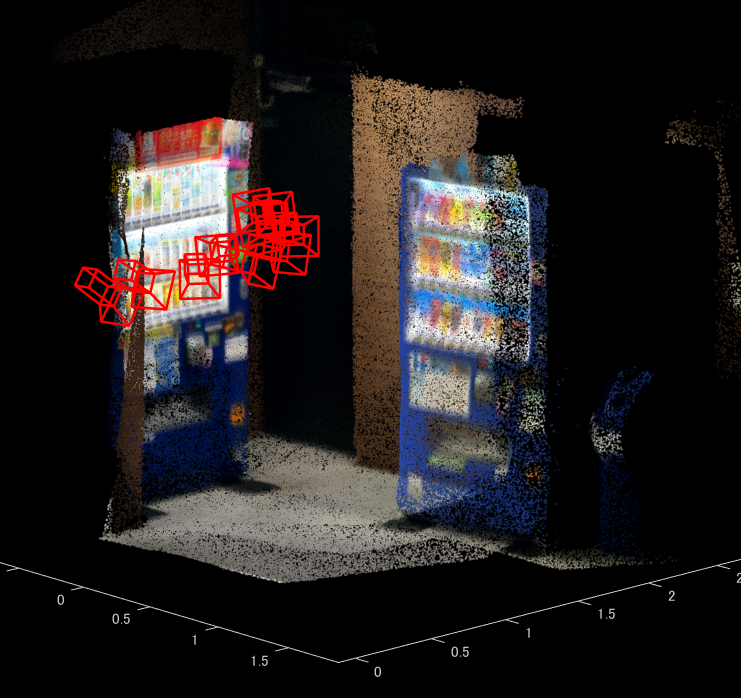

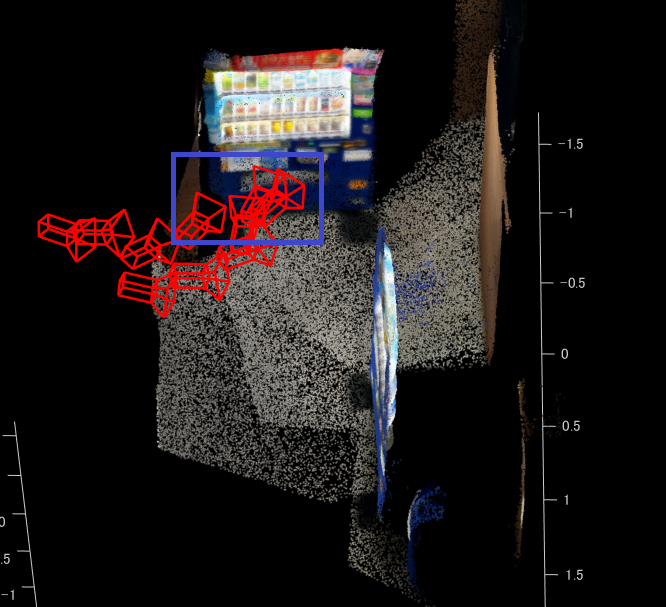

clear;clc;close all

e57Reader = e57FileReader("lobby.e57");

ptCloudArr = [];
tformArr = []; 

% 点群データを読み取ります。
ax = figure;
% v = VideoWriter(filename);
% open(v)
for i = 1:e57Reader.NumPointClouds
   [ptCloud,pcMetadata] = readPointCloud(e57Reader,i);
    for j = 1:numel(ptCloud)
        ptCloudArr = [ptCloudArr ptCloud(j)];
        tformArr = [tformArr pcMetadata.RelativePose];
        cam = plotCamera(AbsolutePose=pcMetadata.RelativePose,Opacity=0,Size=0.1);hold on
        pcshow(pctransform(ptCloud(j),pcMetadata.RelativePose))
        view(45,45);
        pcMap = pcalign(ptCloudArr,tformArr);
        pcshow(pcMap);drawnow
        % img =getframe();
        % imOut = imresize(img.cdata,[436,413]);
        % writeVideo(v,imOut)
        
    end
end

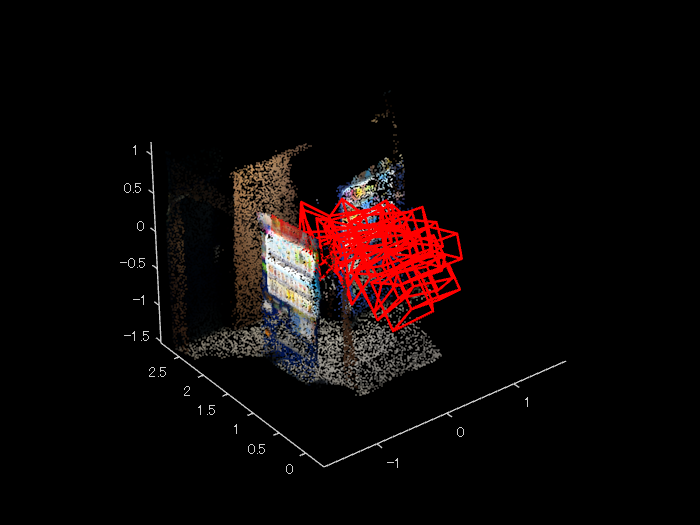


close(v)